clear; clc; close all; 
addpath( "../../NE 500/Error Functions/")
bigBeta = 0.006524; 
bigLambda = 2
beta = [0.038, 0.213, 0.188, 0.407, 0.128, 0.0226] * bigBeta;
lambda = [0.012716, 0.031798, 0.115525, 0.310828, 1.397474, 3.3872331]; 


# First Pull

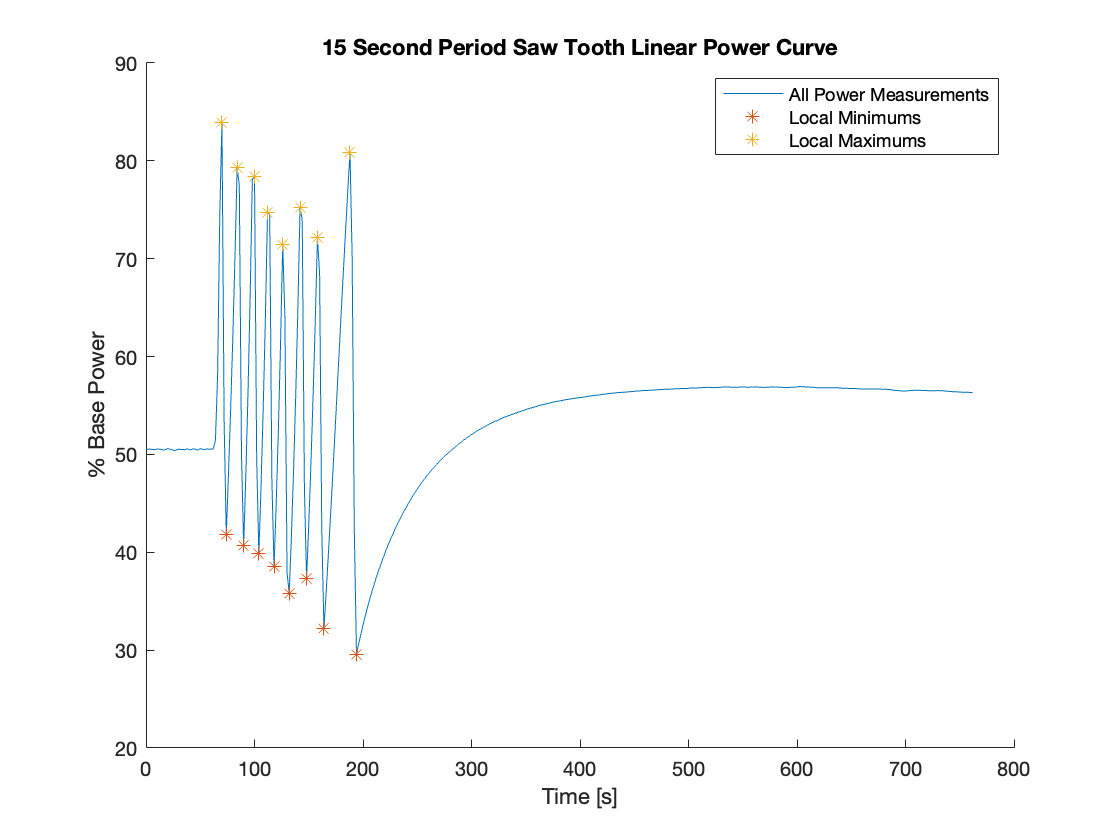

raw = readmatrix( "NE403 Lab 3 Power Defect Lab 08 March 2021.xls", "Range", "D6:I387", "Sheet", "Period 1");

linear = raw( :, 3:4 );
linear = mean( linear, 2 );
time = ( 0:2:( 2 * numel( linear ) - 1 ) )';

mins = islocalmin( linear ) & time > 60 & time < 300;
maxs = islocalmax( linear ) & time > 60 & time < 300;

minidx = find( mins );
maxidx = find( maxs );

region1 = 1:maxidx( 1 );
region2 = minidx( 1 ):maxidx( 2 ); 
region3 = minidx( 2 ):maxidx( 3 );
region4 = minidx( 3 ):maxidx( 4 );
region5 = minidx( 4 ):maxidx( 5 );
region6 = minidx( 5 ):maxidx( 6 );
region7 = minidx( 6 ):maxidx( 7 );
region8 = minidx( 7 ):maxidx( 8 );
region9 = ( minidx( 8 ) + 1):numel( linear );


figure() 
hold on 
    title( "15 Second Period Saw Tooth Linear Power Curve")
    xlabel( "Time [s]")
    ylabel( "% Base Power")
    plot( time, linear )
    plot( time( mins ), linear( mins ), '*')
    plot( time( maxs ), linear( maxs ), '*')
    legend( {'All Power Measurements', 'Local Minimums', 'Local Maximums'})
hold off 

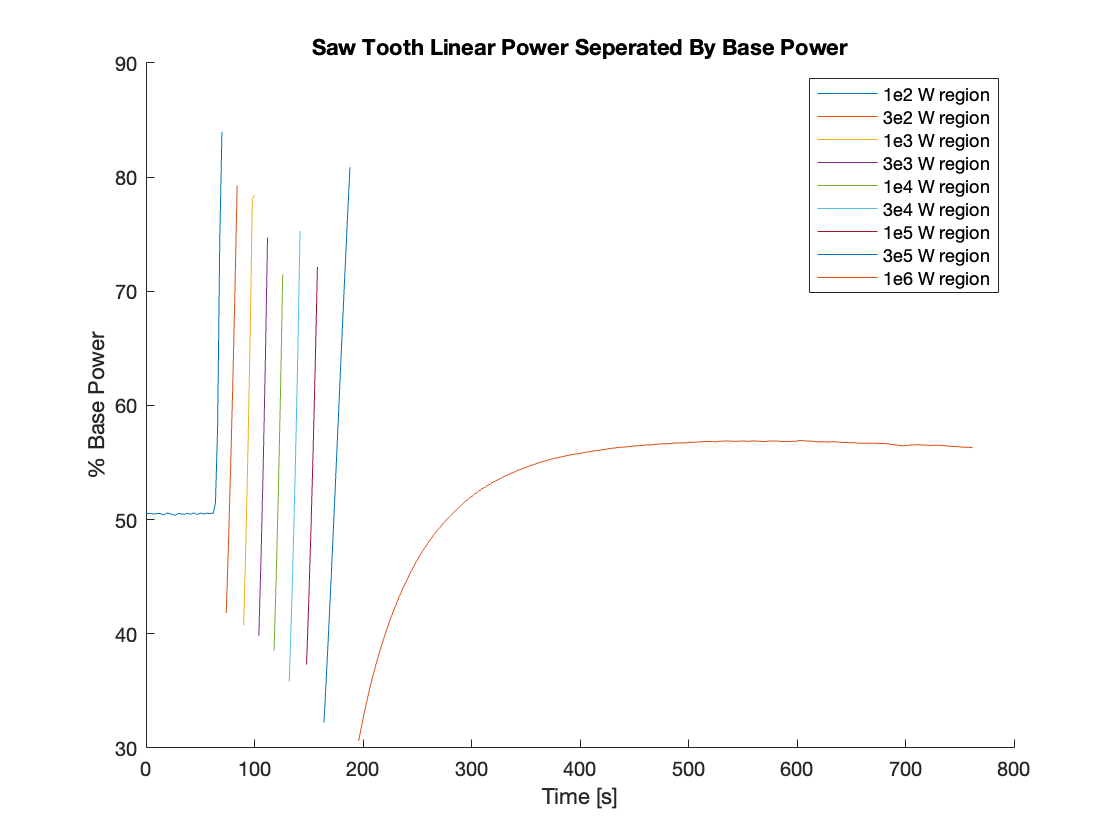


figure() 
hold on 
    title( "Saw Tooth Linear Power Seperated By Base Power")
    xlabel( "Time [s]")
    ylabel( "% Base Power")
    plot( time( region1 ), linear( region1 ))
    plot( time( region2 ), linear( region2 ))
    plot( time( region3 ), linear( region3 ))
    plot( time( region4 ), linear( region4 ))
    plot( time( region5 ), linear( region5 ))
    plot( time( region6 ), linear( region6 ))
    plot( time( region7 ), linear( region7 ))
    plot( time( region8 ), linear( region8 ))
    plot( time( region9 ), linear( region9 ))
    legend( {'1e2 W region', '3e2 W region', ...
             '1e3 W region', '3e3 W region', ...
             '1e4 W region', '3e4 W region', ...
             '1e5 W region', '3e5 W region', ...
             '1e6 W region'})
hold off 

linear = linear / 100; 
adjustedlinear = [ linear( region1 ) * 1e2; ... 
                   linear( region2 ) * 3e2; ...
                   linear( region3 ) * 1e3; ...
                   linear( region4 ) * 3e3; ...
                   linear( region5 ) * 1e4; ...
                   linear( region6 ) * 3e4; ...
                   linear( region7 ) * 1e5; ...
                   linear( region8 ) * 3e5; ...
                   linear( region9 ) * 1e6]; 

adjustedtime = [ time( region1 ); ... 
                 time( region2 ); ...
                 time( region3 ); ...
                 time( region4 ); ...
                 time( region5 ); ...
                 time( region6 ); ...
                 time( region7 ); ...
                 time( region8 ); ...
                 time( region9 )]; 

increaseRegion = [ region5, region6, region6, region7, region8];

initialPower = adjustedlinear( increaseRegion( 1 ));
eIdx = find( adjustedlinear( increaseRegion ) > initialPower * exp( 1 ), 1 )

eIdx = 6

reactorPeriod = adjustedtime( increaseRegion( eIdx) ) - adjustedtime( increaseRegion( 1 ) ) 

reactorPeriod = 18

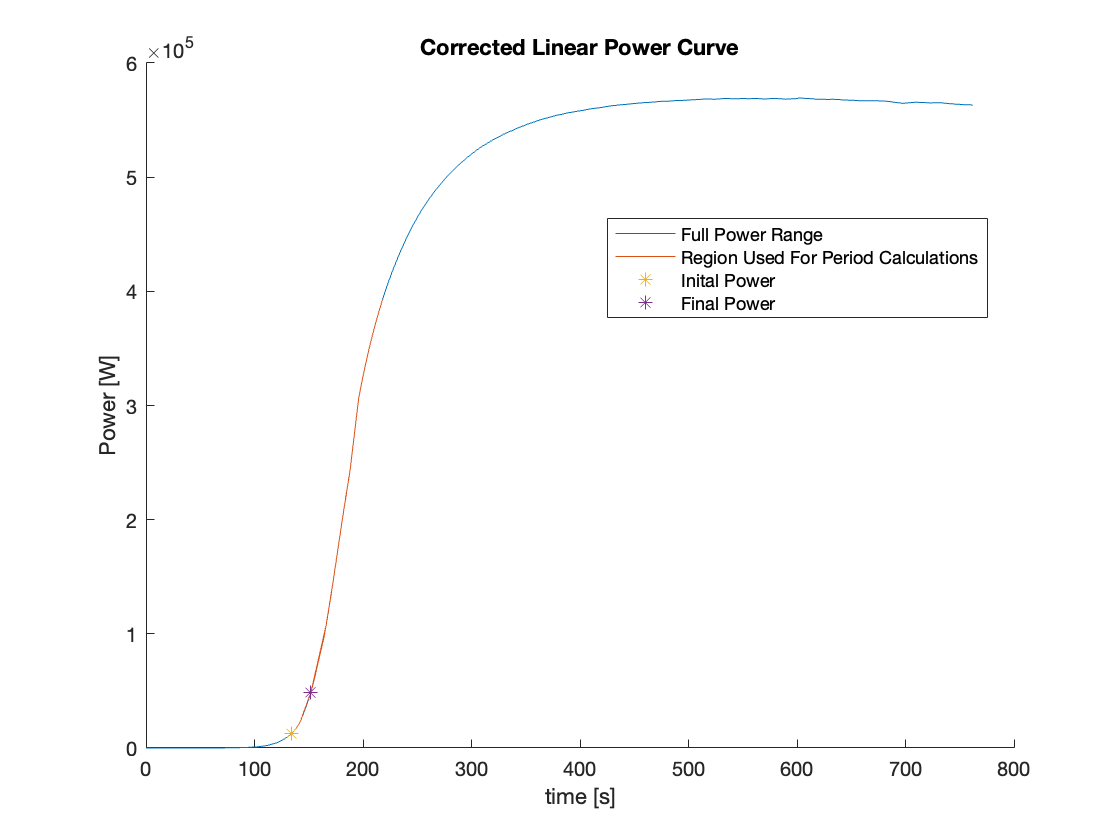


figure() 
hold on
    title( "Corrected Linear Power Curve")
    xlabel( "time [s]")
    ylabel( "Power [W]")
    plot( adjustedtime, adjustedlinear )
    plot( adjustedtime( increaseRegion ), adjustedlinear( increaseRegion))
    plot( adjustedtime( increaseRegion( 1 )), adjustedlinear( increaseRegion( 1 )), '*')
    plot( adjustedtime( increaseRegion( eIdx )), adjustedlinear( increaseRegion( eIdx ) ), '*')
    legend( {'Full Power Range', 'Region Used For Period Calculations', 'Inital Power', 'Final Power'}, 'location','best')
hold off 

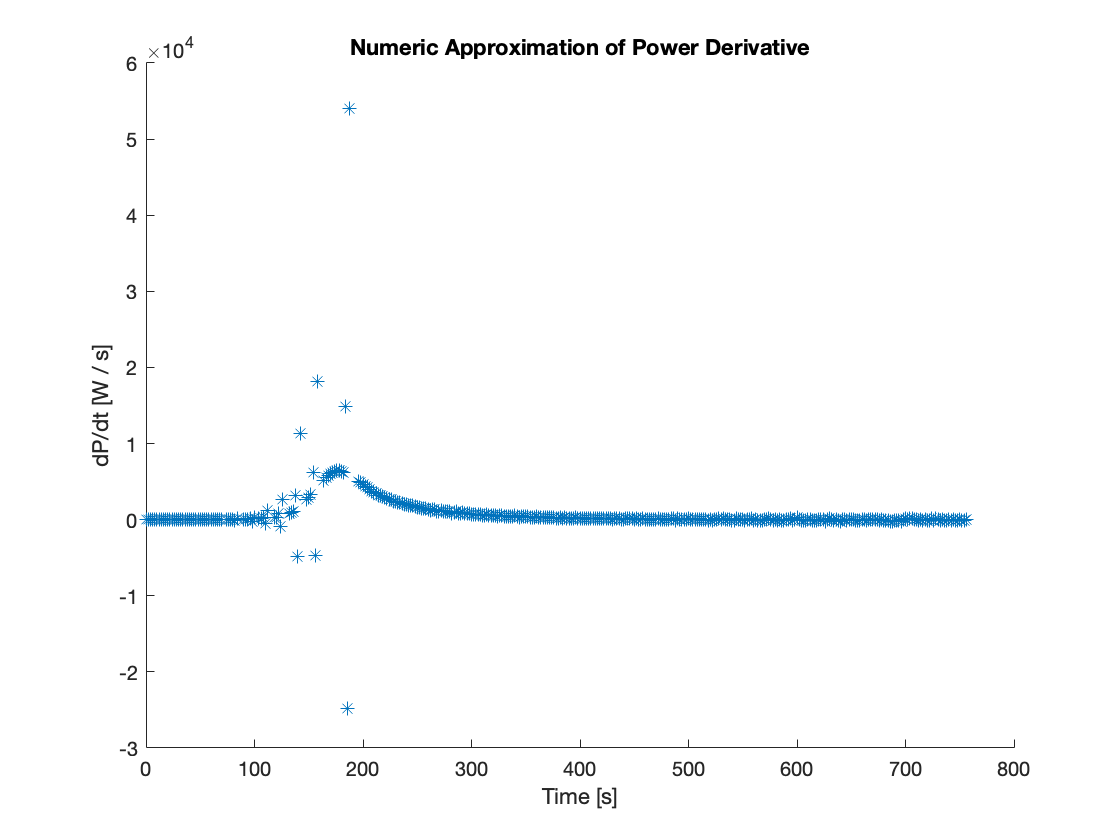

derivatives = zeros( numel( adjustedlinear) - 3, 1 );
for i = 1:numel( adjustedlinear ) - 3 
    derivatives( i ) = finiteDifference3( adjustedtime, adjustedlinear, adjustedtime( i ), 2 );
end 
figure() 
hold on 
    title( "Numeric Approximation of Power Derivative")
    xlabel( "Time [s]")
    ylabel( "dP/dt [W / s]")
    plot( adjustedtime( 1:end-3 ), derivatives, '*')
hold off 

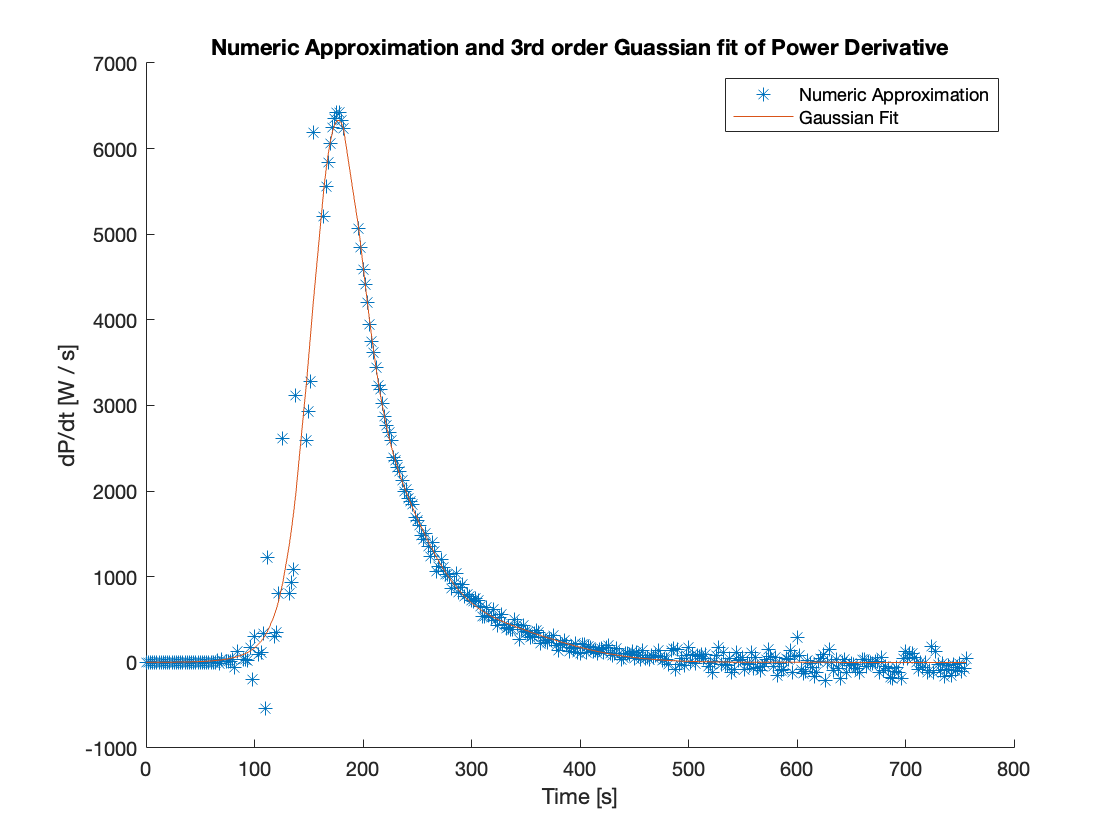

tokeep = derivatives >= -872 & derivatives < 1e4;
filteredtime = adjustedtime( 1:end - 3);
filteredtime = filteredtime( tokeep );
derivatives = derivatives( tokeep );

derivativeFit = fit( filteredtime, derivatives, 'gauss3');
figure()
hold on 
    title( "Numeric Approximation and 3rd order Guassian fit of Power Derivative")
    xlabel( "Time [s]")
    ylabel( "dP/dt [W / s]")
    plot( filteredtime , derivatives, '*' ) 
    plot( filteredtime, derivativeFit( filteredtime ))
    legend( {'Numeric Approximation', 'Gaussian Fit'})
hold off 

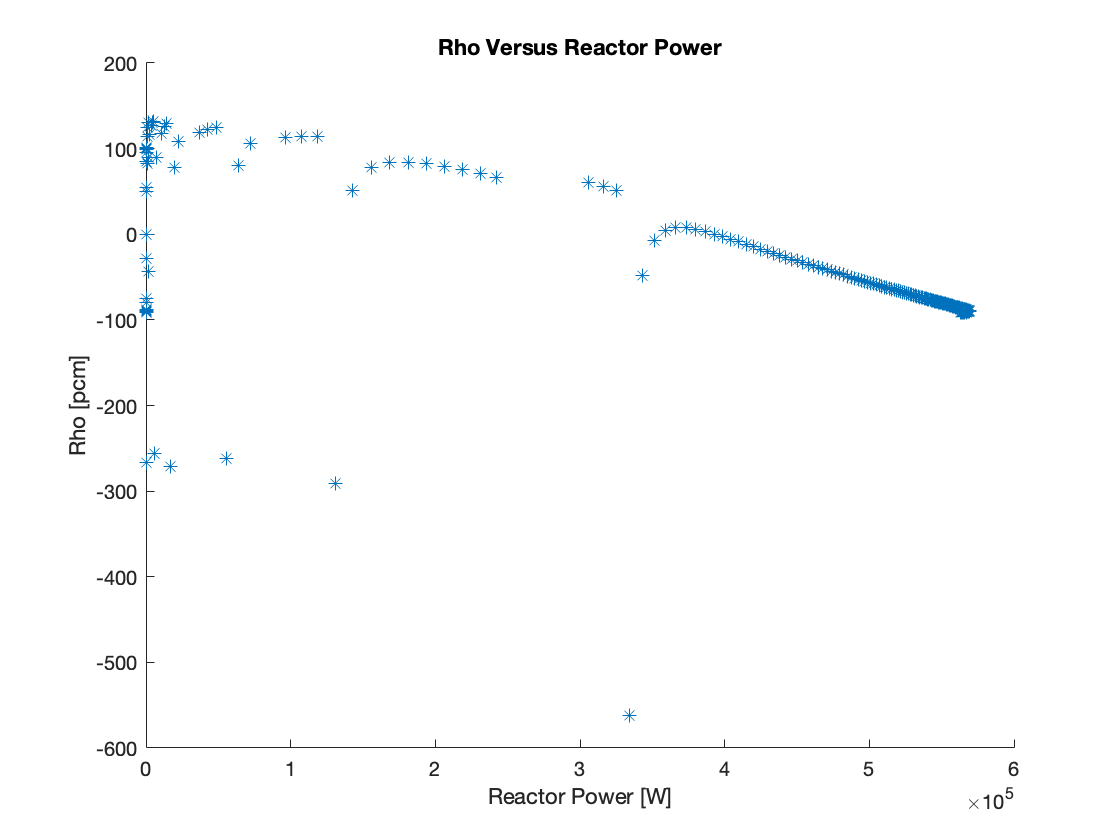


rho_in_time = zeros( numel( adjustedtime ) - 3, 1 );
for i = 3:numel( rho_in_time )
    %rho_in_timefit( i ) = reactivity( adjustedtime( i ) , adjustedtime, PowerFit, bigBeta, beta, bigLambda, lambda, derivativeFit);
    rho_in_time( i ) = reactivity( adjustedtime( i ) , adjustedtime, adjustedlinear, bigBeta, beta, bigLambda, lambda, derivativeFit);
end


maxrho = max( rho_in_time );
maxpower = adjustedlinear( rho_in_time == maxrho );

endrho = rho_in_time( find( adjustedlinear == adjustedlinear( end ), 1));
endpower = adjustedlinear( rho_in_time == endrho );
linearfit = polyfit( [maxpower, endpower], [maxrho, endrho], 1 );
powerrange = adjustedlinear( 1 ):10:adjustedlinear( end );
rhovals = polyval( linearfit, powerrange );
figure()
hold on 
    title('Rho Versus Reactor Power')
    xlabel( 'Reactor Power [W]')
    ylabel( 'Rho [pcm]')
    plot( adjustedlinear(4:end), rho_in_time * 1e5, '*' );
    %plot( powerrange, rhovals )
    %legend( {'Calculated Values', 'Linear Fit'})
hold off 

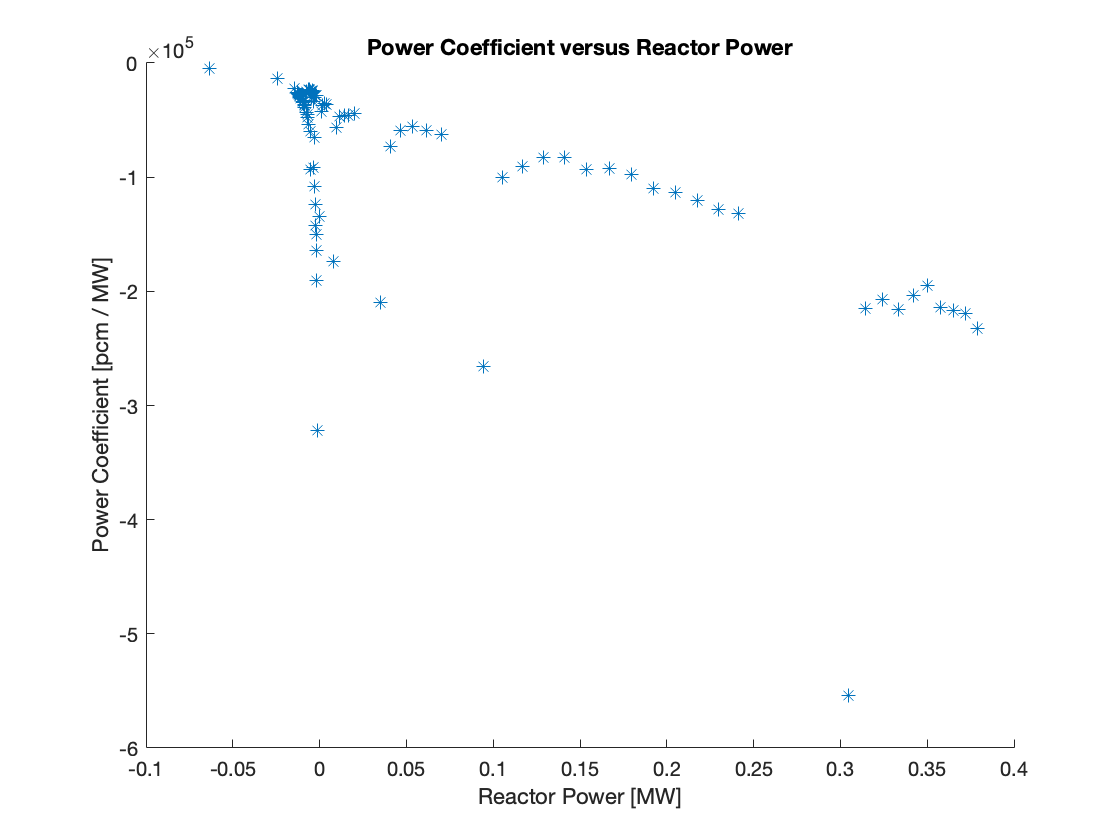

rhop = rho_in_time *1e5 - 240 - 3.9 * ( 89.06 - 88.7 );
adjustedlinear = adjustedlinear( 1:end -3 );
powerdiff = ( adjustedlinear( 1:end -1 ) - adjustedlinear( 2:end ) ) * 1e-6;
rhop = rhop( 2:end );

powerdiff = powerdiff( abs( powerdiff ) > 1e-3 );
rhop = rhop( abs( powerdiff ) > 1e-3);
alpha = rhop ./ abs( powerdiff ) ;

rhop_pows = adjustedlinear( 2:end )* 1e-6;
rhop_pows = rhop_pows( abs( powerdiff ) > 1e-3 );
figure() 
hold on
    plot( rhop_pows + powerdiff, alpha, '*')
    title( 'Power Coefficient versus Reactor Power')
    xlabel( 'Reactor Power [MW]')
    ylabel( 'Power Coefficient [pcm / MW]')
hold off 

mean( alpha)

ans = -8.5958e+04

std( alpha ) 

ans = 8.5707e+04

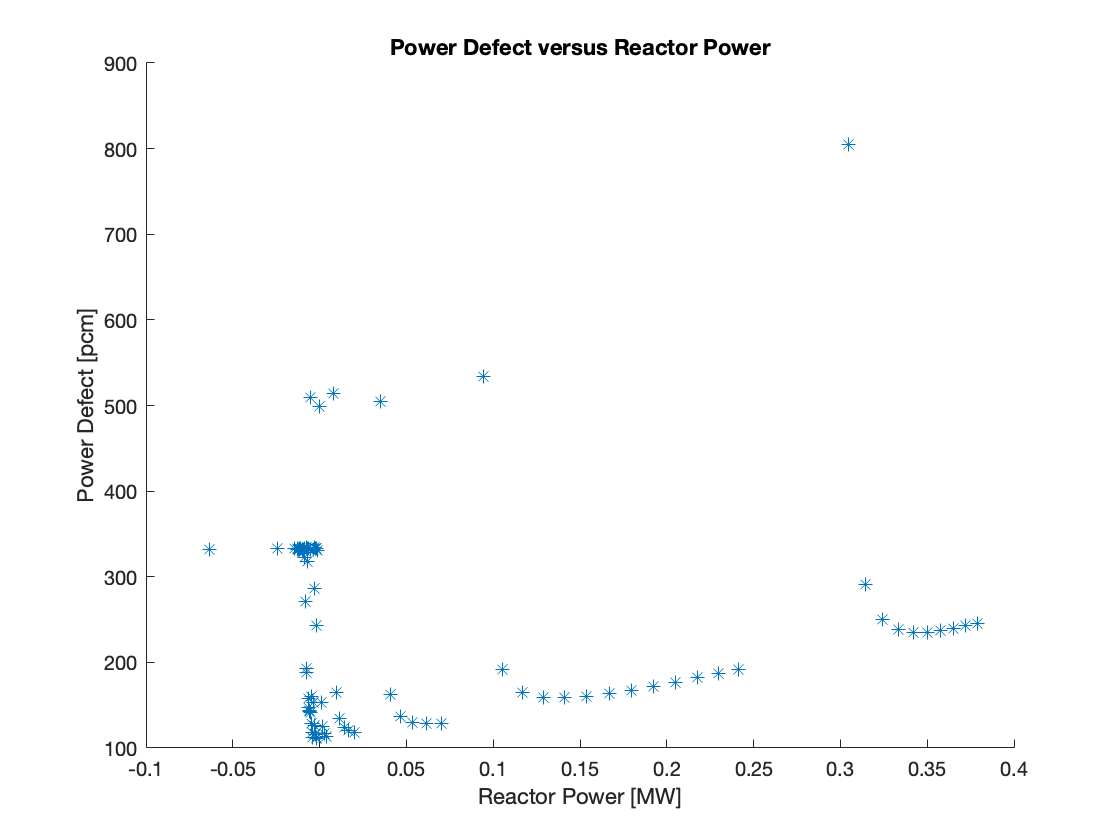

power_defect = abs( rhop - 3.9 * ( 89.06 - 88.7  ));

figure() 
hold on     
    title( 'Power Defect versus Reactor Power')
    xlabel( 'Reactor Power [MW]')
    ylabel( 'Power Defect [pcm]')
    plot( rhop_pows + powerdiff, power_defect, '*' )
hold off 

meanPower_defect = mean( power_defect)

meanPower_defect = 252.0292

error = std( power_defect )

error = 121.3201

# Second Pull 

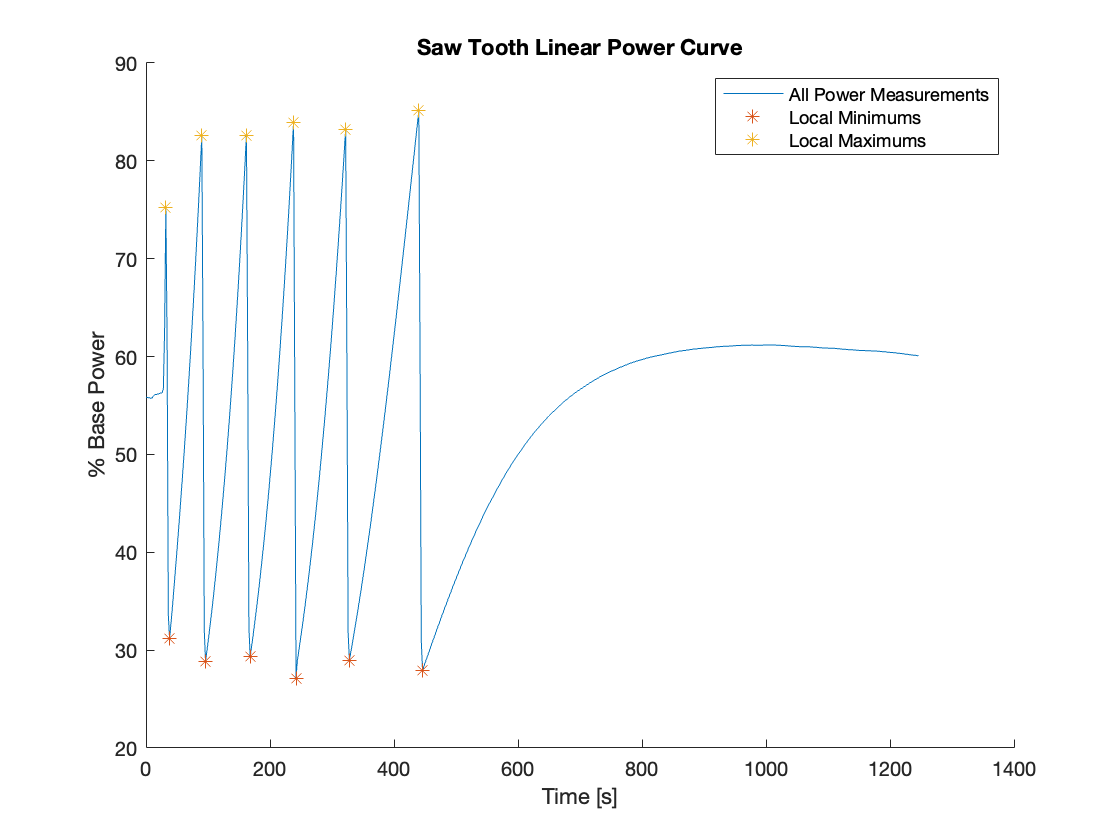

clc; clear; 

bigBeta = 0.006524; 
bigLambda = 5.5960e-05;
beta = [0.038, 0.213, 0.188, 0.407, 0.128, 0.0226] * bigBeta;
lambda = [0.012716, 0.031798, 0.115525, 0.310828, 1.397474, 3.3872331]; 

raw = readmatrix( "NE403 Lab 3 Power Defect Lab 08 March 2021.xls", "Range", "D6:I629", "Sheet", "Period 2");

linear = raw( :, 3:4 );
linear = mean( linear, 2 );
time = ( 0:2:( 2 * numel( linear ) - 1 ) )';

mins = islocalmin( linear ) & time > 30 & time < 600;
maxs = islocalmax( linear ) & time > 30 & time < 600;

minidx = find( mins );
maxidx = find( maxs );

region1 = 1:maxidx( 1 );
region2 = minidx( 1 ):maxidx( 2 ); 
region3 = minidx( 2 ):maxidx( 3 );
region4 = minidx( 3 ):maxidx( 4 );
region5 = minidx( 4 ):maxidx( 5 );
region6 = minidx( 5 ):maxidx( 6 );
region7 = minidx( 6 ):numel( linear );

figure() 
hold on 
    title( "Saw Tooth Linear Power Curve")
    xlabel( "Time [s]")
    ylabel( "% Base Power")
    plot( time, linear )
    plot( time( mins ), linear( mins ), '*')
    plot( time( maxs ), linear( maxs ), '*')
    legend( {'All Power Measurements', 'Local Minimums', 'Local Maximums'})
hold off 

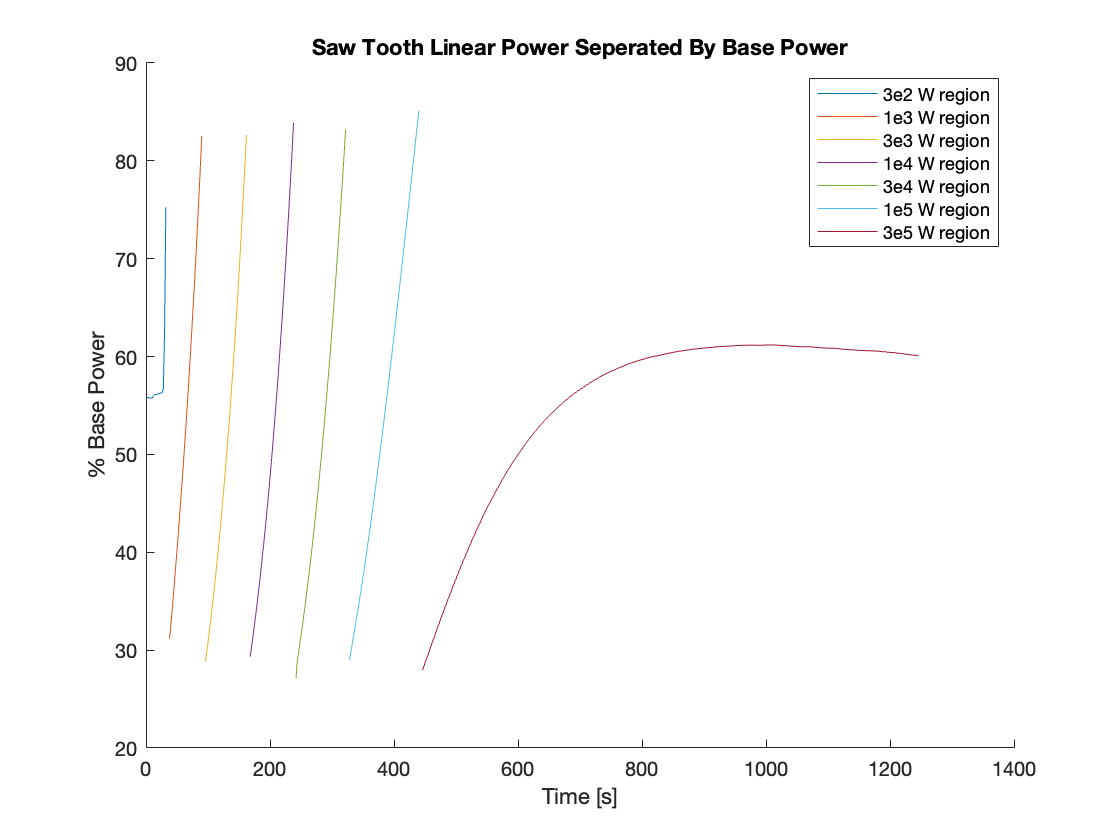


figure() 
hold on 
    title( "Saw Tooth Linear Power Seperated By Base Power")
    xlabel( "Time [s]")
    ylabel( "% Base Power")
    plot( time( region1 ), linear( region1 ))
    plot( time( region2 ), linear( region2 ))
    plot( time( region3 ), linear( region3 ))
    plot( time( region4 ), linear( region4 ))
    plot( time( region5 ), linear( region5 ))
    plot( time( region6 ), linear( region6 ))
    plot( time( region7 ), linear( region7 ))
    legend( {'3e2 W region', '1e3 W region', ...
             '3e3 W region', '1e4 W region', ...
             '3e4 W region', '1e5 W region', ...
             '3e5 W region'})
hold off 

linear = linear / 100; 
adjustedlinear = [ linear( region1 ) * 3e2; ... 
                   linear( region2 ) * 1e3; ...
                   linear( region3 ) * 3e3; ...
                   linear( region4 ) * 1e4; ...
                   linear( region5 ) * 3e4; ...
                   linear( region6 ) * 1e5; ...
                   linear( region7 ) * 3e5];

adjustedtime = [ time( region1 ); ... 
                 time( region2 ); ...
                 time( region3 ); ...
                 time( region4 ); ...
                 time( region5 ); ...
                 time( region6 ); ...
                 time( region7 )];

increaseRegion = [ region5, region6 ];


initialPower = adjustedlinear( increaseRegion( 1 ));

eIdx = find( adjustedlinear( increaseRegion ) > initialPower * exp( 1 ), 1 )

eIdx = 35

reactorPeriod = adjustedtime( increaseRegion( eIdx) ) - adjustedtime( increaseRegion( 1 ) ) 

reactorPeriod = 72

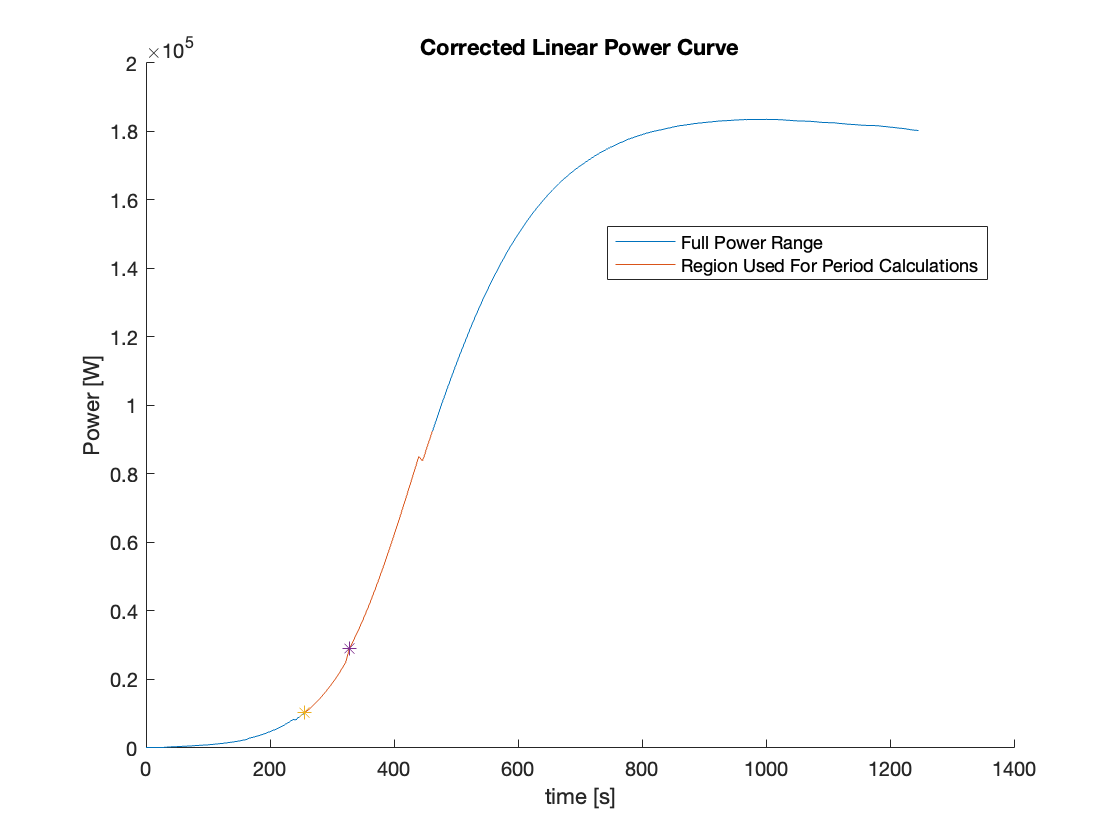

figure() 
hold on
    title( "Corrected Linear Power Curve")
    xlabel( "time [s]")
    ylabel( "Power [W]")
    plot( adjustedtime, adjustedlinear )
    plot( adjustedtime( increaseRegion ), adjustedlinear( increaseRegion))
    plot( adjustedtime( increaseRegion( 1 )), adjustedlinear( increaseRegion( 1 )), '*')
    plot( adjustedtime( increaseRegion( eIdx )), adjustedlinear( increaseRegion( eIdx ) ), '*')
    legend( {'Full Power Range', 'Region Used For Period Calculations'}, 'location','best')
hold off 

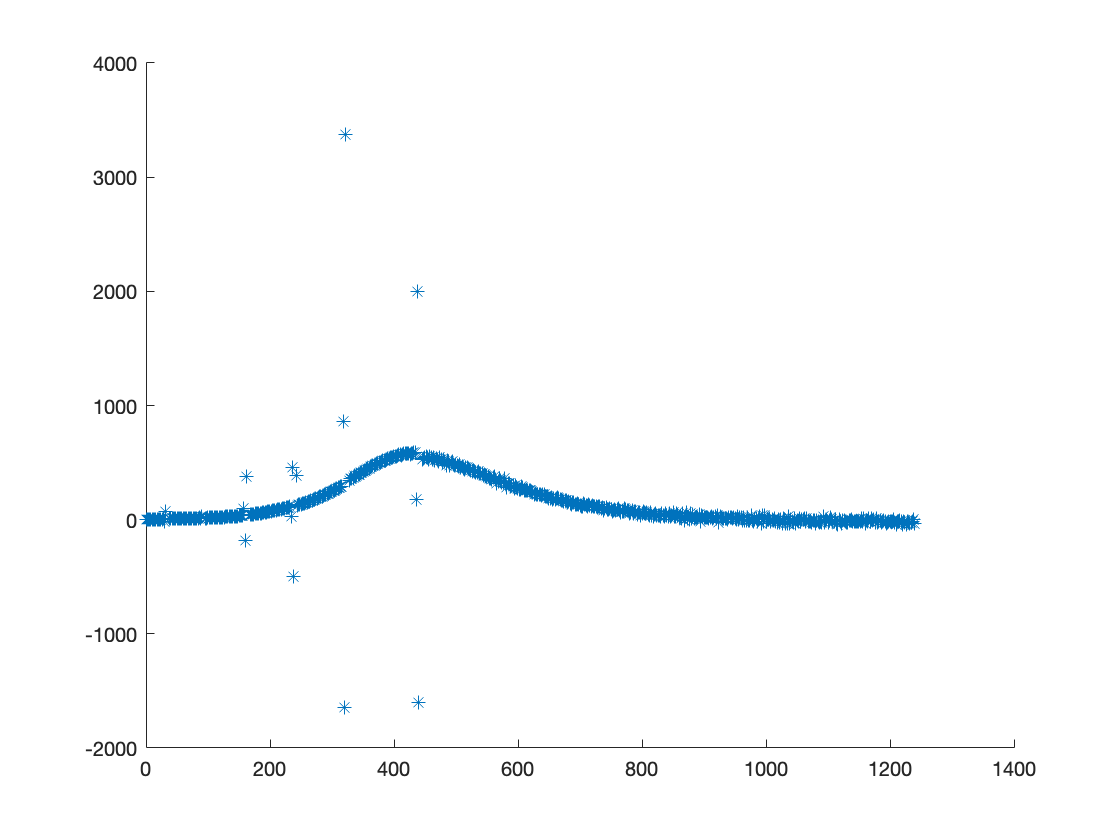

derivatives = zeros( numel( adjustedlinear) - 3, 1 );
for i = 1:numel( adjustedlinear ) - 3 
    derivatives( i ) = finiteDifference3( adjustedtime, adjustedlinear, adjustedtime( i ), 2 );
end 
figure() 
hold on 
    plot( adjustedtime( 1:end-3 ), derivatives, '*')
hold off 

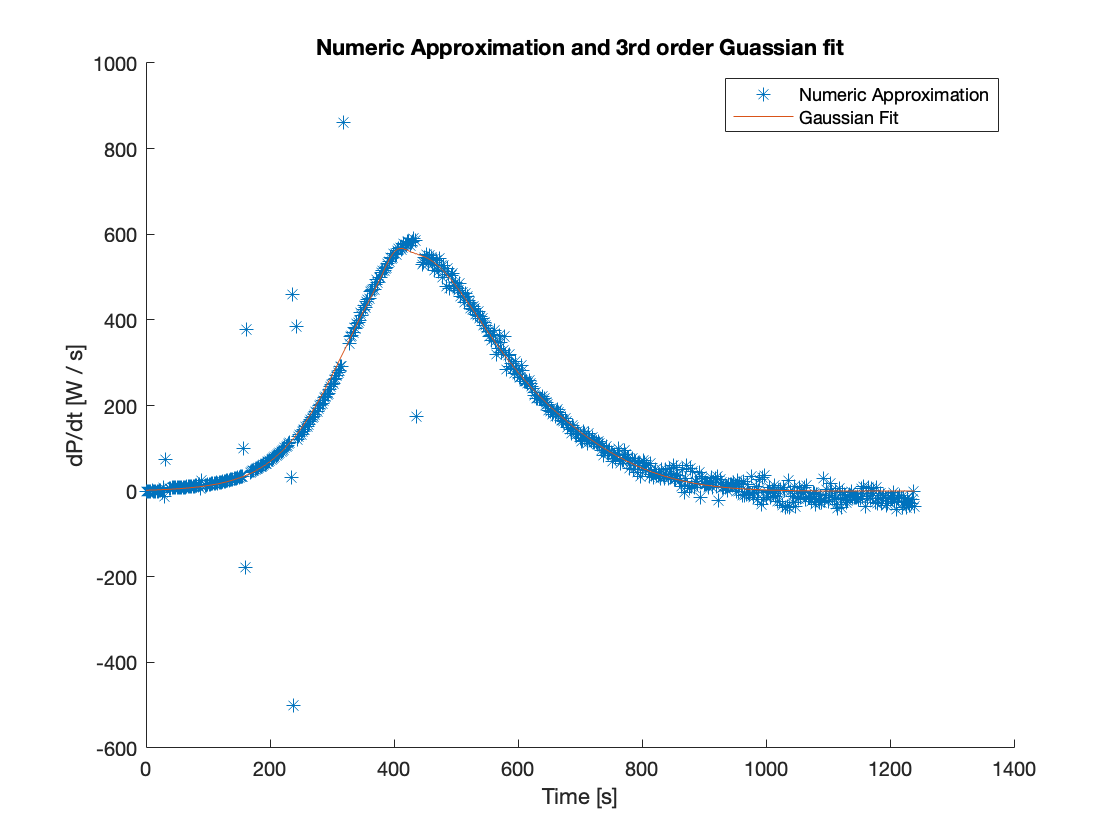

tokeep = derivatives >= -872 & derivatives < 1000;
filteredtime = adjustedtime( 1:end - 3);
filteredtime = filteredtime( tokeep );
derivatives = derivatives( tokeep );

derivativeFit = fit( filteredtime, derivatives, 'gauss3');
figure()
hold on 
    title( "Numeric Approximation and 3rd order Guassian fit")
    xlabel( "Time [s]")
    ylabel( "dP/dt [W / s]")
    plot( filteredtime , derivatives, '*' ) 
    plot( filteredtime, derivativeFit( filteredtime ))
    legend( {'Numeric Approximation', 'Gaussian Fit'})
hold off 


rho_in_time = zeros( numel( adjustedtime ) - 3, 1 );
for i = 3:numel( rho_in_time )
    %rho_in_timefit( i ) = reactivity( adjustedtime( i ) , adjustedtime, PowerFit, bigBeta, beta, bigLambda, lambda, derivativeFit);
    rho_in_time( i ) = reactivity( adjustedtime( i ) , adjustedtime, adjustedlinear, bigBeta, beta, bigLambda, lambda, derivativeFit);
end


maxrho = max( rho_in_time );
maxpower = adjustedlinear( rho_in_time == maxrho );

endrho = rho_in_time( find( adjustedlinear == adjustedlinear( end ), 1))

endrho = -8.7427e-04

endpower = adjustedlinear( rho_in_time == endrho )

endpower = 180255

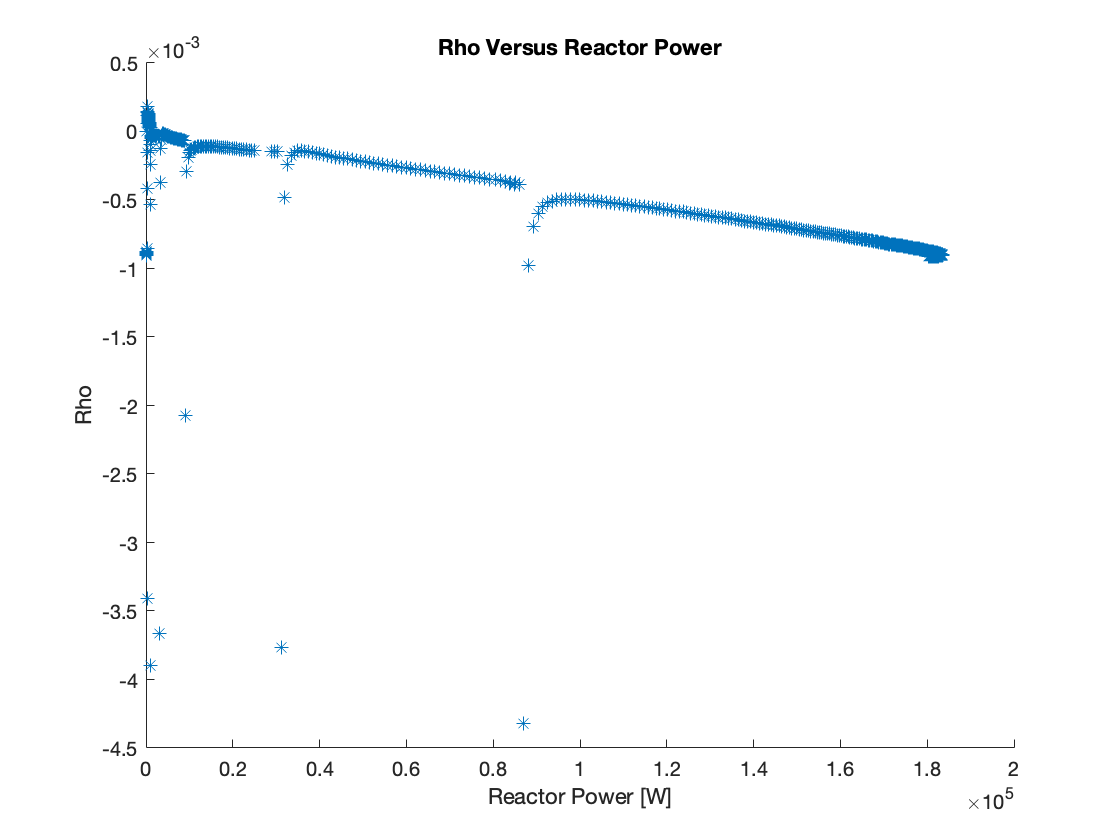

linearfit = polyfit( [maxpower, endpower], [maxrho, endrho], 1 );
powerrange = adjustedlinear( 1 ):10:adjustedlinear( end );
rhovals = polyval( linearfit, powerrange );
figure()
hold on 
    title('Rho Versus Reactor Power')
    xlabel( 'Reactor Power [W]')
    ylabel( 'Rho')
    plot( adjustedlinear(4:end), rho_in_time, '*' );
    %plot( powerrange, rhovals )
    %legend( {'Calculated Values', 'Linear Fit'})
hold off 

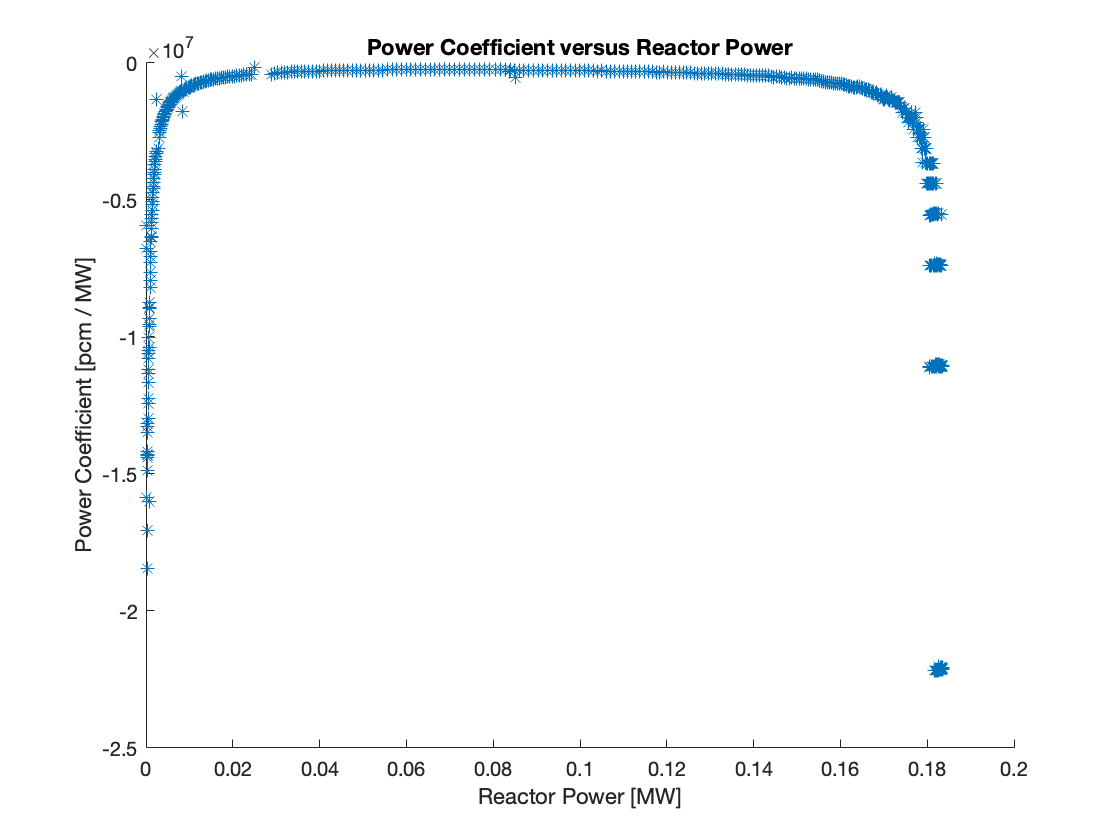

rhop = rho_in_time *1e5 - 240 - 3.9 * ( 89.06 - 88.7 );
adjustedlinear = adjustedlinear( 1:end -3 );
powerdiff = ( adjustedlinear( 1:end -1 ) - adjustedlinear( 2:end ) ) * 1e-6;
rhop = rhop( 2:end );

filter = powerdiff ~= 0; 

powerdiff = powerdiff( filter );
rhop = rhop( filter );
alpha = rhop ./ abs( powerdiff ) ;

rhop_pows = adjustedlinear( 2:end )* 1e-6;
rhop_pows = rhop_pows( filter  );

filter = abs( alpha ) <= 0.5e8;
figure() 
rhop_pows = rhop_pows( filter );
powerdiff = powerdiff( filter );
alpha = alpha( filter );
hold on
    plot( rhop_pows + powerdiff, alpha, '*')
    title( 'Power Coefficient versus Reactor Power')
    xlabel( 'Reactor Power [MW]')
    ylabel( 'Power Coefficient [pcm / MW]')
hold off 

mean( alpha)

ans = -5.4618e+06

std( alpha )

ans = 6.5996e+06

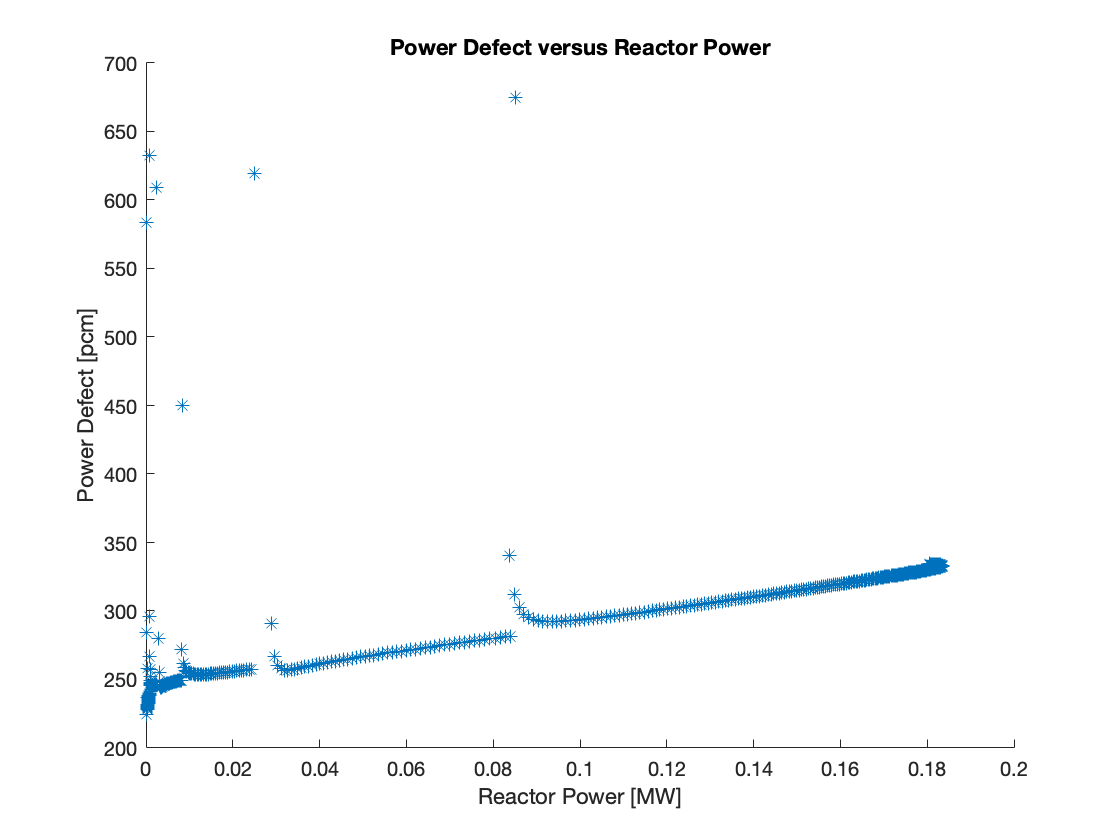

power_defect = abs( rhop - 3.9 * ( 89.06 - 88.7  ));
 
power_defect = power_defect( filter );
figure() 
hold on     
    title( 'Power Defect versus Reactor Power')
    xlabel( 'Reactor Power [MW]')
    ylabel( 'Power Defect [pcm]')
    plot( rhop_pows + powerdiff, power_defect, '*' )
hold off 

meanPower_defect = mean( power_defect)

meanPower_defect = 303.5883

std( power_defect)

ans = 46.9256

syms h A B C D
T =  [ 1, 0, 0, 0; ...
      1, h, (h)^2 / 2, (h)^3 / 6; ...
      1, 2 * h, (2 * h)^2 / 2, (2 * h)^3 / 6; ...; 
      1, 3 * h, (3 * h)^2 / 2, (3 * h)^3 / 6; ...; 
      ]' / h

$$T = \left(\begin{array}{cccc} \frac{1}{h} & \frac{1}{h} & \frac{1}{h} & \frac{1}{h}\\ 0 & \frac{\bar{h}}{h} & \frac{2\,\bar{h}}{h} & \frac{3\,\bar{h}}{h}\\ 0 & \frac{{\left(\bar{h}\right)}^{2}}{2\,h} & \frac{2\,{\left(\bar{h}\right)}^{2}}{h} & \frac{9\,{\left(\bar{h}\right)}^{2}}{2\,h}\\ 0 & \frac{{\left(\bar{h}\right)}^{3}}{6\,h} & \frac{4\,{\left(\bar{h}\right)}^{3}}{3\,h} & \frac{9\,{\left(\bar{h}\right)}^{3}}{2\,h} \end{array}\right)$$

x = [A;B;C;D]

$$x = \left(\begin{array}{c} A\\ B\\ C\\ \text{D} \end{array}\right)$$

b = [ 0; 1; 0; 0]

b =      0
     1
     0
     0


coef = inv( T ) * b 

$$coef = \left(\begin{array}{c} -\frac{11\,h}{6\,\bar{h}}\\ \frac{3\,h}{\bar{h}}\\ -\frac{3\,h}{2\,\bar{h}}\\ \frac{h}{3\,\bar{h}} \end{array}\right)$$

R = 1 / h * [ 0, (h)^4 / 24, (2 * h)^4 / 24, (3 * h)^4 / 24] * coef 

$$R = \frac{h^{4}}{4\,\bar{h}}$$